# 2020-07-30 Opto meta analysis

This analysis will be largely similar to the 2020-07-27 analysis, but will display the data differently. 

The previous analysis looked at the effects of GtACR1 and CsChrimson expressed in different LN types, for the same stimulus.

This analysis will look at the effects of GtACR1 and CsChrimson expressed in a given LN type, across all stimuli.

## Get and filter the experiment names

expNames = unique(fetchn(ephys.Experiment, 'exp_name'));
disp(expNames)

    {'NP1227-Gal4_ACR1 R26A01-LexA_LexAop-mCD8-GFP_PN'                    }
    {'NP1227-Gal4_UAS_CsChrimson R26A01-LexA_LexAop-mCD8-GFP_LN'          }
    {'NP1227-Gal4_UAS_CsChrimson R26A01-LexA_LexAop-mCD8-GFP_PN'          }
    {'NP1227-Gal4_UAS_CsChrimson R26A01-LexA_LexAop-mCD8-GFP_unlabeled_LN'}
    {'NP1227-Gal4_UAS_CsChrimson R26A01-LexA_LexAop-mCD8-GFP_unlabeled_PN'}
    {'NP1227-gal4_X_20x-UAS-GtACR1'                                       }
    {'R24C12-Gal4_ACR1 R26A01-LexA_LexAop-mCD8-GFP_LN'                    }
    {'R24C12-Gal4_ACR1 R26A01-LexA_LexAop-mCD8-GFP_PN'                    }
    {'R24C12-Gal4_UAS_CsChrimson R26A01-LexA_LexAop-mCD8-GFP_PN'          }
    {'R24C12-gal4_X_20x-UAS-GtACR1'                                       }
    {'R24C12-gal4_X_20x-UAS-GtACR1_unlabeled'                             }
    {'R24C12-gal4_X_UAS-CsChrimson-mVenus'                                }
    {'R55D11-Gal4_UAS_CsChrimson R26A01-LexA_LexAop-mCD8-GFP_PN'          }
    {'R78F09

Now remove experiment types that we're not going to analyze right now (opsin controls, unlabeled PNs). Since there are few types (and for clarity) I will just be manually re-entering expNames

clear expNames
expNames{1} = 'NP1227-Gal4_ACR1 R26A01-LexA_LexAop-mCD8-GFP_PN';
expNames{2} = 'NP1227-Gal4_UAS_CsChrimson R26A01-LexA_LexAop-mCD8-GFP_PN';
expNames{3} = 'NP1227-Gal4_UAS_CsChrimson R26A01-LexA_LexAop-mCD8-GFP_unlabeled_LN';
expNames{4} = 'R24C12-Gal4_ACR1 R26A01-LexA_LexAop-mCD8-GFP_PN';
expNames{5} = 'R24C12-Gal4_UAS_CsChrimson R26A01-LexA_LexAop-mCD8-GFP_PN';
expNames{6} = 'R55D11-Gal4_UAS_CsChrimson R26A01-LexA_LexAop-mCD8-GFP_PN';
expNames{7} = 'R78F09-Gal4_ACR1 R26A01-LexA_LexAop-mCD8-GFP_PN';
expNames{8} = 'R78F09-Gal4_UAS_CsChrimson R26A01-LexA_LexAop-mCD8-GFP_PN';

and some reformatting for later...

fmtNames(1,1) = expNames(1);
fmtNames(1,2) = expNames(2);
fmtNames(2,1) = expNames(4);
fmtNames(2,2) = expNames(5);
fmtNames(3,2) = expNames(6);
fmtNames(4,1) = expNames(7);
fmtNames(4,2) = expNames(8);

## Manually annotate DC3 PNs

This should have been done prior and included in the database, will fix this in a future database import

t = readtable('/Users/asa/Downloads/2020-07-23_Experiment_table_import.xlsx');

s = table2struct(t);
for i = 1:length(s)
    s(i).data_path = ['/Volumes/SSD_DATA', s(i).data_path(21:end)];
end
s = rmfield(s, 'Exp__');
s = rmfield(s, 'Stack');
s = rmfield(s, 'PhysiologyComments');
s = rmfield(s, 'AnatomyComments');
s = rmfield(s, 'ExpressionComments');
i_exclude = 1:91;
s(i_exclude) = [];
s(13).CellType = {'DC3_adPN'};
s(40).CellType = {'DC3_adPN'};
s(53).CellType = {'DC3_adPN'};
s(54).CellType = {'DC3_adPN'};
s(55).CellType = {'DC3_adPN'};
s(56).CellType = {'DC3_adPN'};
s(57).CellType = {'DC3_adPN'};
s(58).CellType = {'DC3_adPN'};
% s(58).exp_name = {'R78F09-Gal4_UAS_CsChrimson R26A01-LexA_LexAop-mCD8-GFP_PN'};
s(61).CellType = {'DC3_adPN'};
s(62).CellType = {'DC3_adPN'};
s(63).CellType = {'DC3_adPN'};
s(64).CellType = {'DC3_adPN'};
s(65).CellType = {'DC3_adPN'};
s(33).exp_name = {'NP1227-Gal4_UAS_CsChrimson R26A01-LexA_LexAop-mCD8-GFP_unlabeled_LN'};

t= struct2table(s);

## Filter experiment list for DC3 PNs

t(~contains(t.CellType, 'DC3'),:) = []

t = 29×5 table
    exp_id         date                                   exp_name                                                                                     data_path                                                            CellType  
    ______    ______________    _____________________________________________________________    _____________________________________________________________________________________________________________________    ____________

     104      {'2019-06-10'}    {'NP1227-Gal4_ACR1 R26A01-LexA_LexAop-mCD8-GFP_PN'          }    {'/Volumes/SSD_DATA/Data/optogenetic_LN_stim/NP1227-Gal4_ACR1 R26A01-LexA_LexAop-mCD8-GFP_PN/2019-06-10'            }    {'DC3_adPN'}
     105      {'2019-06-13'}    {'NP1227-Gal4_ACR1 R26A01-LexA_LexAop-mCD8-GFP_PN'          }    {'/Volumes/SSD_DATA/Data

## Construct query

odorQuery = ephys.Trial * ephys.Experiment * ephys.Analyzed & 'odor_stim=1' & 'spacer_trial=0' & 'trial_block=1';

waveforms = {'1_second', 'fast', 'med', 'slow'};
odors = {'2-hep', 'farnesol'};
concentrations = [6, 5, 4, 3, 2, 1];
% waveforms = {'fast'};
% odors = {'farnesol'};
% concentrations = [4,2, 1];

for iLN = 1:4
for iOdor = 1:length(odors)
for iWav = 1:length(waveforms)


## Iterate through experiments and fill data tensors, plot and save results

clear psth vm_filt spike_inds
nExp = zeros(4,2);
for iConc = 1:length(concentrations)
    for iOpsin = 1:2
        exp_name = fmtNames{iLN, iOpsin};
        if isempty(exp_name)
            nExp(iConc, iOpsin) = 0;
            continue
        end
        type_inds = find(contains(t.exp_name, exp_name));
        if isempty(type_inds)
            nExp(iConc, iOpsin) = 0;
            continue
        end
        for iExp = 1:length(type_inds)
            for opto_on = 0:1
                % finish setting query parameters
                exp_condition = ['exp_id=' num2str(t.exp_id(type_inds(iExp)))];
                wav_condition = ['wave_name="' waveforms{iWav} '"'];
                odor_condition = ['odor="' odors{iOdor} '"'];
                conc_condition = ['concentration=' num2str(concentrations(iConc))];
                q = odorQuery & exp_condition;
                q = q * ephys.TrialOdor & wav_condition & conc_condition & odor_condition;
                q = q & ['opto_stim=' num2str(opto_on)];
                
                % fetch trials, skip if none of that type
                trial_t = q.fetch('psth', 'vm_filt', 'trial_name', 'spike_inds');
                if isempty(trial_t)
                    continue
                end
                trial_t = struct2table(trial_t);
                
                % remove non-standard trials, this should be handled at the
                % database level in later versions.
                trial_t(contains(trial_t.trial_name, 'depolarized'), :) = [];
                trial_t(contains(trial_t.trial_name, 'hyperpolarized'), :) = [];
                trial_t(contains(trial_t.trial_name, '-45'), :) = [];
                trial_t(contains(trial_t.trial_name, '-60'), :) = [];
                trial_t(contains(trial_t.trial_name, 'TTX'), :) = [];
                trial_t(contains(trial_t.trial_name, 'picrotoxin'), :) = [];
                trial_t(contains(trial_t.trial_name, 'CGP'), :) = [];
                trial_t(contains(trial_t.trial_name, 'Vclamp'), :) = [];
                trial_t(contains(trial_t.trial_name, 'end_of_experiment'), :) = [];
                trial_t(contains(trial_t.trial_name, 'oscillation'), :) = [];
                
                % fill data tensors with experiment means
                p = cell2mat(trial_t.psth(:)');
                v = cell2mat(trial_t.vm_filt(:)');
                p_mean = nanmean(p,2) * 10 * 1e3;
                v_mean = nanmean(v,2);
                p_mean(p_mean == 0) = Inf;     % hack
                v_mean(v_mean == 0) = Inf;     % hack
                psth(:,iConc, iOpsin, opto_on+1, iExp) = p_mean; % this factor is correct, but where does it come from?
                vm_filt(:,iConc, iOpsin, opto_on+1, iExp) = v_mean;
            end
        end
    end
end
% Convert empty experiments form 0s to NaNs
if ~exist('psth', 'var')
    continue
end
psth(psth == 0) = NaN;
vm_filt(vm_filt == 0) = NaN;
psth(isinf(psth)) = 0;
vm_filt(isinf(vm_filt)) = 0;
for iOpsin = 1:size(psth,3)
    for iConc = 1:size(psth,2)
        nExp(iConc, iOpsin) = squeeze(sum(~isnan(psth(1,iConc,iOpsin,2,:)),5));
    end
end

## Pretty plot - effect for one sitmulus across opsins and LN types

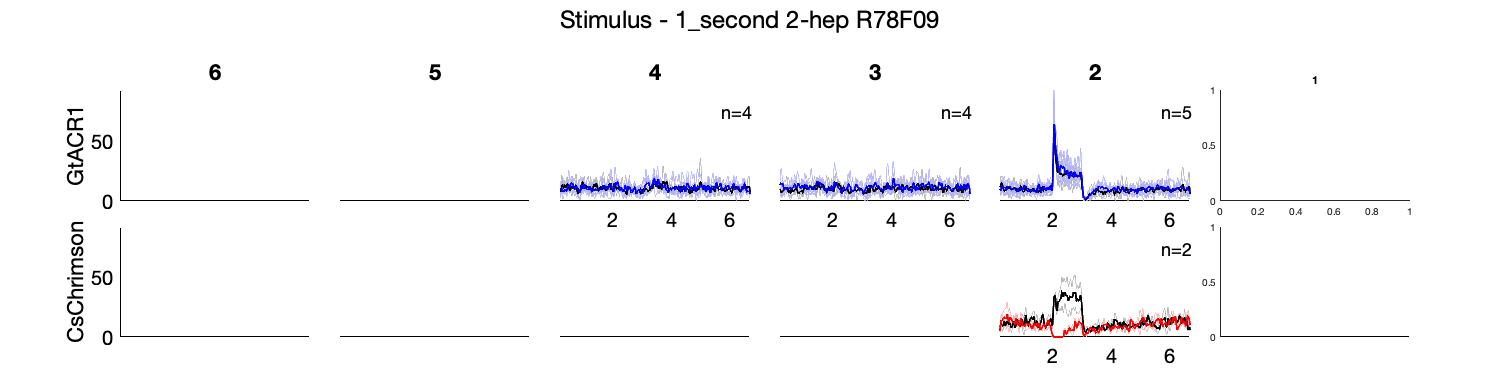

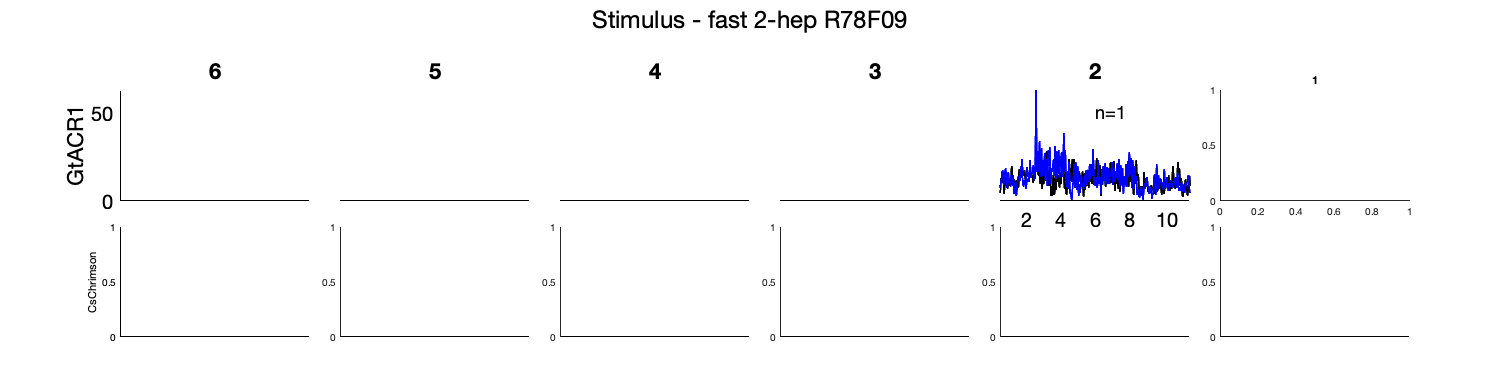

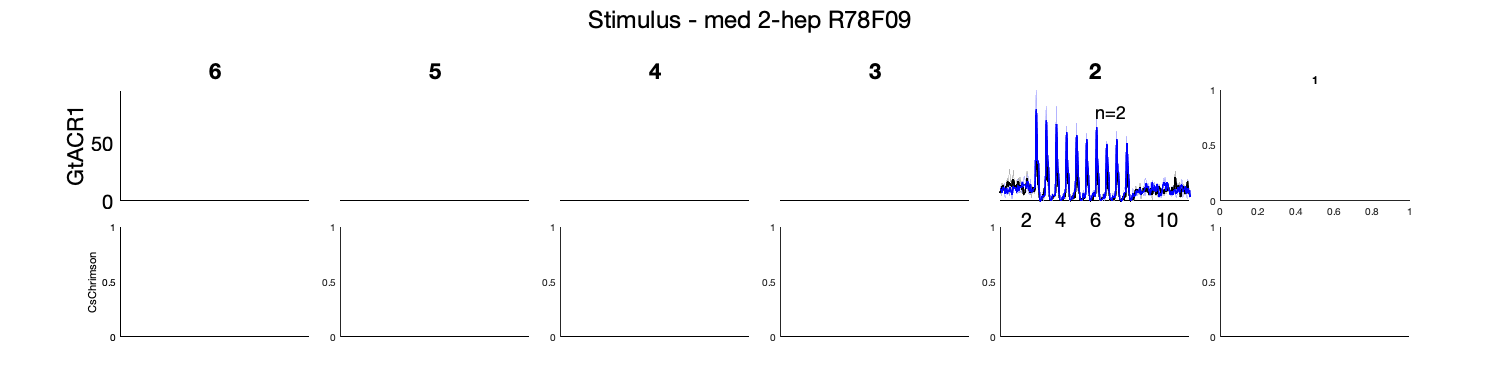

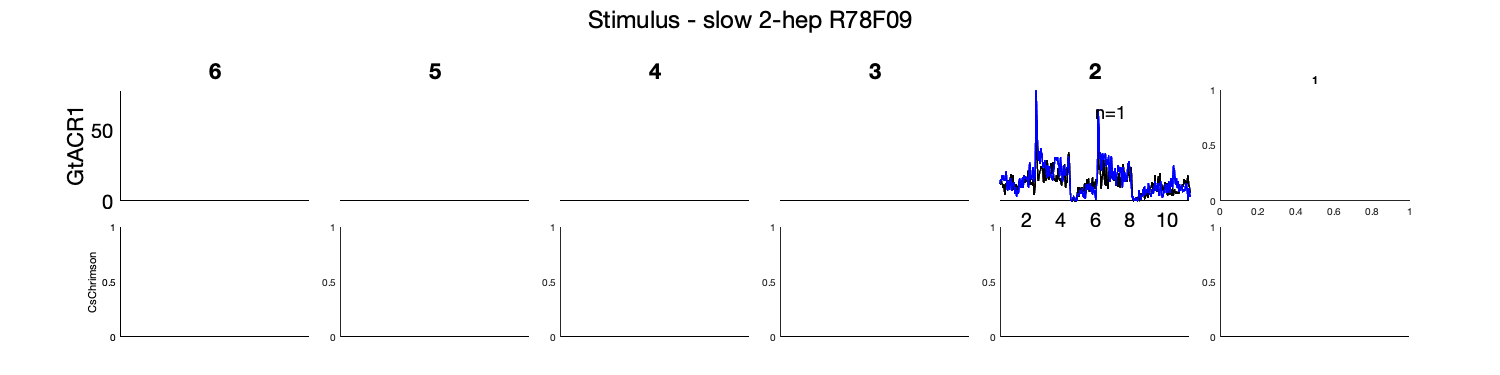

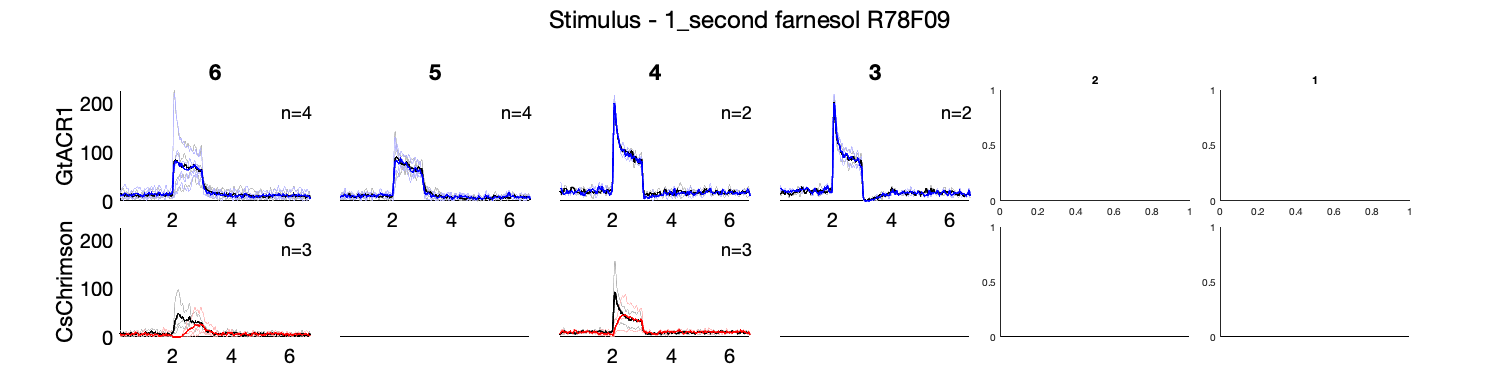

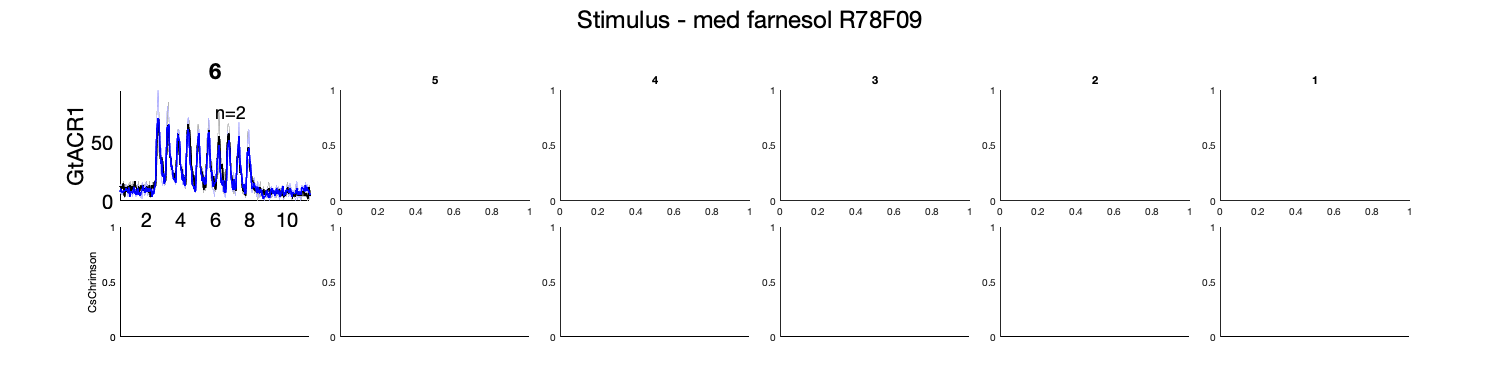

ylim = max(psth(:));
figure
subplot = @(m,n,p) subtightplot (m, n, p, [0.07 0.02], [0.1 0.24], [0.08 0.06]);

for iConc = 1:size(psth,2)%4
    for iOpsin = 1:size(psth,3)%2
        iPlot = sub2ind([6,2], iConc, iOpsin);
        fig = subplot(2, 6, iPlot);
        ax = gca;
        hold on
        if iOpsin ==1
            trialColor = [0.7 0.7 1];
            meanColor = [0 0 1];
        else
            trialColor = [1 0.7 0.7];
            meanColor = [1 0 0];
        end
        plot(squeeze(psth(:,iConc, iOpsin, 1, :)), 'color', [0.7 0.7 0.7], 'linewidth', 1.4)
        plot(squeeze(psth(:,iConc, iOpsin, 2, :)), 'color', trialColor, 'linewidth', 1.4)        
        plot(nanmean(psth(:,iConc, iOpsin, 1, :), 5), 'k', 'linewidth', 2.2)
        plot(nanmean(psth(:,iConc, iOpsin, 2, :), 5), 'color', meanColor, 'linewidth', 2.2)
        set(ax, 'ylim', [0 ylim], 'box', 'off', 'xcolor', 'none', 'ycolor', 'none', 'fontsize', 20)
        set(gca, 'xcolor', 'k', 'xtick', 2e3:2e3:size(psth,1), 'xticklabels', 2:2:(size(psth,1)/10))
        text(5.5e3, 0.8*ylim, ['n=' num2str(nExp(iConc, iOpsin))], 'fontsize', 18)
    end
end

lnTypes = {'NP1227', 'R24C12', 'R55D11', 'R78F09'};
for iConc = 1:6
    iPlot = sub2ind([6,2], iConc, 2);
    fig = subplot(2, 6, iPlot);
    set(gca, 'xcolor', 'k', 'xtick', 2e3:2e3:size(psth,1), 'xticklabels', 2:2:(size(psth,1)/10))
    iPlot = sub2ind([6,2], iConc, 1);
    fig = subplot(2, 6, iPlot);
    title(concentrations(iConc))
end
opsins = {'GtACR1', 'CsChrimson'};
for iOpsin = 1:2
    iPlot = sub2ind([6,2], 1, iOpsin);
    fig = subplot(2, 6, iPlot);
    set(gca, 'ycolor', 'k')
    ylabel(opsins(iOpsin))
end
set(gcf, 'Position', [0,0,1500,375]);
fig = gcf;

title_name = ['Stimulus - ' waveforms{iWav} ' ' odors{iOdor} ' ' num2str(lnTypes{iLN})];
sgtitle(title_name, 'interpreter', 'none', 'fontsize', 24)
% print([saveDir filesep 'png' filesep expName, '.png'], '-dpng', '-r0')
% print([title_name '.png'], '-dpng', '-r300');
% savefig(gcf, [title_name '.fig'])
end
end
end

% figure
% subplot(2,4,1)
% for iConc = 1:4
%     for iPert = 1:2
%         iPlot = sub2ind([4,2], iConc, iPert);
%         subplot(2, 4, iPlot)
%         
%         hold on
%         if isempty(expNames{iPlot})
%             continue
%         end
%         exp_condition = ['exp_name="' fmtNames{iConc, iPert} '"'];
%         q = odorQuery & exp_condition;
%         q = q * ephys.TrialOdor & 'wave_name="1_second"' & 'concentration=2' & 'odor="2-hep"';
%         q = q * ephys.Analyzed;
%         trial_t = q.fetch('psth', 'vm_filt', 'trial_name');
%         if isempty(trial_t)
%             continue
%         end
%         trial_t = struct2table(trial_t);
%         for iTrial = 1:size(trial_t,1)
%             odorPsth(:,iTrial) = trial_t.psth{iTrial};
%             plot(odorPsth(:,iTrial), 'color', [0.8 0.8 0.8])
%             set(gca, 'ylim', [0 0.015])
%         end
%         
%         if isempty(expNames{iPlot})
%             continue
%         end
%         exp_condition = ['exp_name="' fmtNames{iConc, iPert} '"'];
%         q = optoQuery & exp_condition;
%         q = q * ephys.TrialOdor & 'wave_name="1_second"' & 'concentration=2' & 'odor="2-hep"';
%         q = q * ephys.Analyzed;
%         trial_t = q.fetch('psth', 'vm_filt', 'trial_name');
%         if isempty(trial_t)
%             continue
%         end
%         trial_t = struct2table(trial_t);
%         for iTrial = 1:size(trial_t,1)
%             optoPsth(:,iTrial) = trial_t.psth{iTrial};
%             plot(optoPsth(:,iTrial), 'color', [0.8 0.8 01])
%             set(gca, 'ylim', [0 0.015])
%         end
%         plot(mean(odorPsth, 2), 'k')
%         plot(mean(optoPsth, 2), 'b')
%     end
% end

% %t = struct2table(fetch(ephys.Trial * ephys.Experiment *ephys.TrialOdor & ['exp_name="' expNames{i} '"'] & 'spacer_trial=0' & 'trial_block=1', '*'));
% 
% e = unique(fetchn(ephys.Trial * ephys.Experiment *ephys.TrialOdor & ['exp_name="' expNames{i} '"'] & 'spacer_trial=0' & 'trial_block=1', 'trial_name'));
